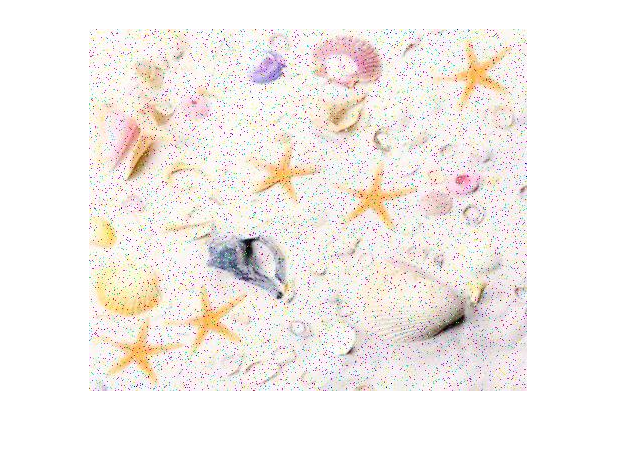

% Computer Vision Coursework Pipeline
% Write the file name to load below, with the extesion, It will
% be expected that it is located within the current directory
FileName = "./workingImages/starfish.jpg";
%FileName = "./notWorking/shellfish_four.jpg";
%FileName = "./workingIMages/starfish_map5.jpg";
%Image Variable that will not be editied (Original)
OriginalImage = LoadImage(FileName);

The first task, after loading the image is to analyse the image histogram and decide what to do with the image

workingImage = OriginalImage

workingImage = 362×438×3 uint8 array
workingImage(:,:,1) =

   255   244   255   255   244   255   255   115   255   255   255   255   255   255   255   255   254   255   255   255   255   249   242   239   255   255   242   249   155   235   237   249   247   247   250   255   255   255   255   255   254   255   255   255   255   249   248   244   237   235   199   227   230   245   255   255   255   250   237   255   255   255   255   254   255   255   119   255   255   255   222   241   253   255   255   240   254   255   255   255   255   255   253   248   255   255   243   255   255   248   236   248   255   249   239   242   231   180   140   234   238   221   255   255   255   255   249   253   252   239   255   255   255   248   255   251   255   250   255   252   253   255   255    98   253   252   255   255   245   248   230   255   255   255   127   255   236   245   255   255   248   255   255   255   255   255   255   253   255   255   239   235   247   218   161   233   2

ThreeChannelHistorgram(workingImage)

ans =     18     5     4     4    10     6     9    11    11    21    19    14     9    14    10    17    20    18    15    14    13    13    15    13    16    14    15     6    13    11    10    15    11    18    21    23    21    21    24    20    32    36    35    49    77    58    65    83   101   101



smallOct = strel('octagon', 3);
  workingImage = deSaltImage(OriginalImage);

red Channel salt and pepper noise


Green Channel Salt and Pepper Noise


Blue Channel Salt and Pepper Noise


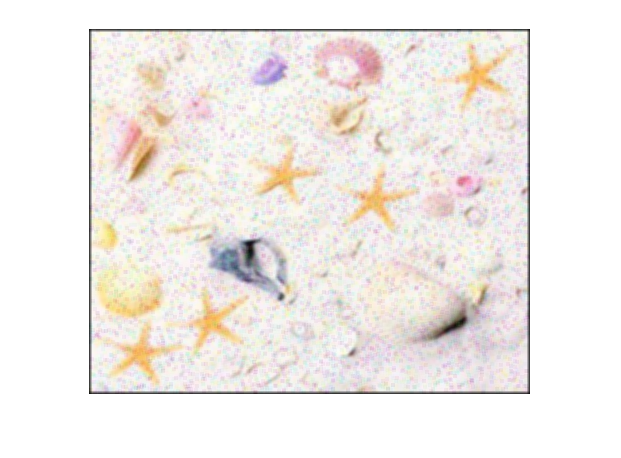

    

   % workingImage = deSaturisedImage(workingImage)
   %S workingImage = uint8(workingImage * 255);
    test = workingImage(:,:,1);
    figure
    imshow(workingImage);

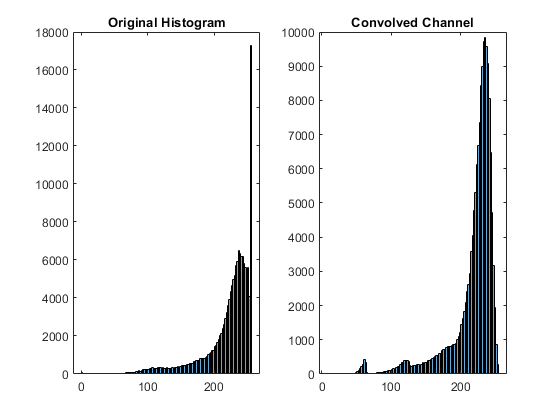

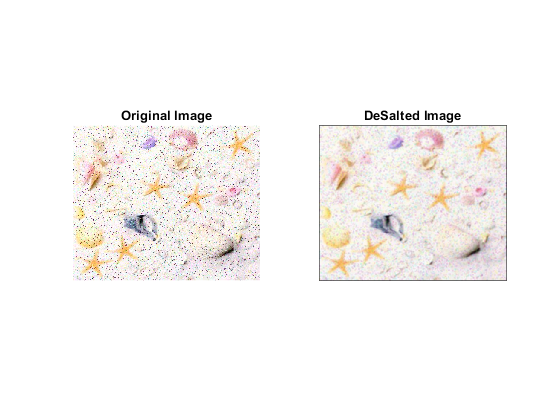

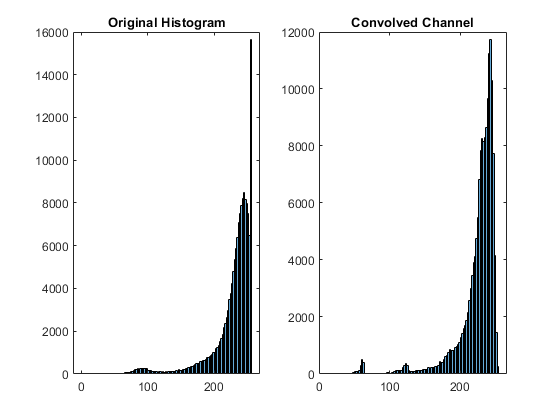

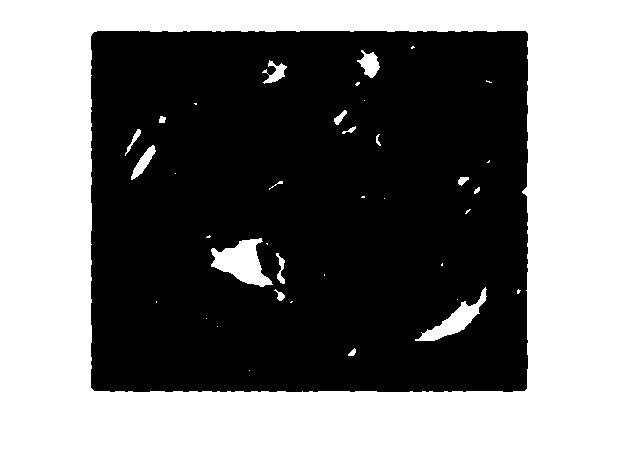



  
    GrayFilteredImage = imcomplement(imbinarize(rgb2gray(workingImage)));
    if(true)
    GrayFilteredImage = imclose(GrayFilteredImage, smallOct);
    end
    figure
    imshow(GrayFilteredImage);

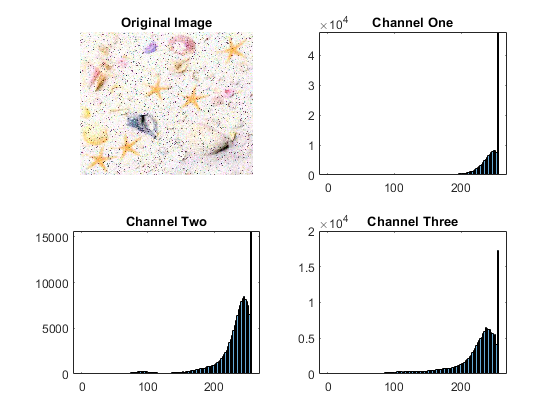

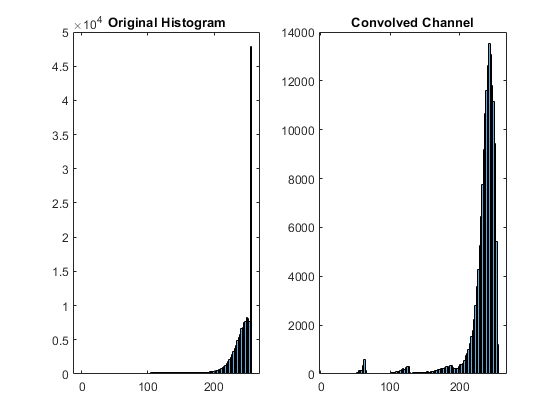

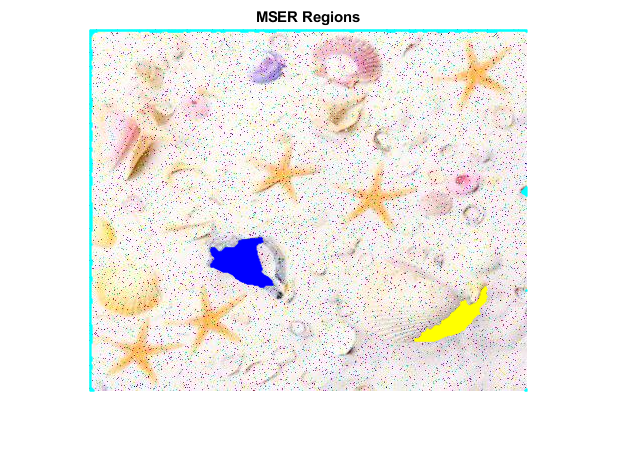

1: BoudningBox:  X: 1.5 Y: 1.5 Eccentricity: 0.54075 Solidity: 0.014973 Area: 2386
2: BoudningBox:  X: 326.5 Y: 258.5 Eccentricity: 0.96943 Solidity: 0.73834 Area: 1061
3: BoudningBox:  X: 122.5 Y: 209.5 Eccentricity: 0.6944 Solidity: 0.76437 Area: 1622
1: BoudningBox:  X: 1.5 Y: 1.5 Eccentricity: 0.54075 Solidity: 0.014973 Area: 2386
2: BoudningBox:  X: 122.5 Y: 209.5 Eccentricity: 0.6944 Solidity: 0.76437 Area: 1622


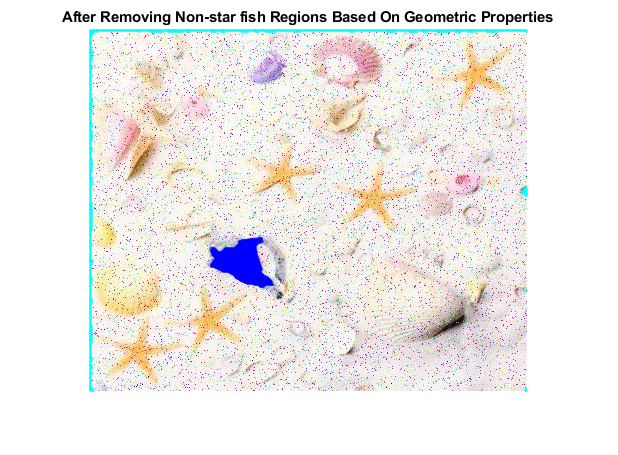

    standardImageAnalysis(GrayFilteredImage, OriginalImage);



%imshow(imbinarize(GreyFilteredImage,graythresh(GreyFilteredImage)));